pcdDir = "~/Downloads/compensated/";
pcdFileNames = [
"1.pcd"
"2.pcd"
"3.pcd"
"4.pcd"
"5.pcd"
"6.pcd"
"7.pcd"
"8.pcd"
"9.pcd"
"10.pcd"
"11.pcd"
"12.pcd"
"13.pcd"
"14.pcd"
"15.pcd"
"16.pcd"
"17.pcd"
"18.pcd"
"19.pcd"
"20.pcd"
"21.pcd"
"22.pcd"
"23.pcd"
"24.pcd"
"25.pcd"
"26.pcd"
"27.pcd"
"28.pcd"
"29.pcd"
"30.pcd"
"31.pcd"
"32.pcd"
"33.pcd"
"34.pcd"
"35.pcd"
"36.pcd"
"37.pcd"
"38.pcd"
"39.pcd"
"40.pcd"
"41.pcd"
"42.pcd"
"43.pcd"
"44.pcd"
"45.pcd"
"46.pcd"
"47.pcd"
"48.pcd"
"49.pcd"
"50.pcd"
"51.pcd"
"52.pcd"
"53.pcd"
"54.pcd"
"55.pcd"
"56.pcd"
"57.pcd"
"58.pcd"
"59.pcd"
"60.pcd"
"61.pcd"
"62.pcd"
"63.pcd"
"64.pcd"
"65.pcd"
"66.pcd"
"67.pcd"
"68.pcd"
"69.pcd"
"70.pcd"
"71.pcd"
"72.pcd"
"73.pcd"
"74.pcd"
"75.pcd"
"76.pcd"
"77.pcd"
"78.pcd"
"79.pcd"
"80.pcd"
"81.pcd"
"82.pcd"
"83.pcd"
"84.pcd"
"85.pcd"
"86.pcd"
"87.pcd"
"88.pcd"
"89.pcd"
"90.pcd"
"91.pcd"
"92.pcd"
"93.pcd"
"94.pcd"
"95.pcd"
"96.pcd"
"97.pcd"
"98.pcd"
"99.pcd"
"100.pcd"
"101.pcd"
"102.pcd"
"103.pcd"
"104.pcd"
"105.pcd"
"106.pcd"
"107.pcd"
"108.pcd"
"109.pcd"
"110.pcd"
"111.pcd"
"112.pcd"
"113.pcd"
"114.pcd"
"115.pcd"
"116.pcd"
"117.pcd"
"118.pcd"
"119.pcd"
"120.pcd"
"121.pcd"
"122.pcd"
]

pcdFileNames = 122×1 string array
    "1.pcd"
    "2.pcd"
    "3.pcd"
    "4.pcd"
    "5.pcd"
    "6.pcd"
    "7.pcd"
    "8.pcd"
    "9.pcd"
    "10.pcd"
    "11.pcd"
    "12.pcd"
    "13.pcd"
    "14.pcd"
    "15.pcd"
    "16.pcd"
    "17.pcd"
    "18.pcd"
    "19.pcd"
    "20.pcd"
    "21.pcd"
    "22.pcd"
    "23.pcd"
    "24.pcd"
    "25.pcd"
    "26.pcd"
    "27.pcd"
    "28.pcd"
    "29.pcd"
    "30.pcd"


## Merge

% Initialize ptCloud using the first file
filepath = fullfile(pcdDir, pcdFileNames(1));
ptCloud = pcread(filepath);

% Load and merge the next set of point clouds
for i = 2:length(pcdFileNames)
    filepath = fullfile(pcdDir, pcdFileNames(i));
    tmpPtCloud = pcread(filepath);
    ptCloud = pcmerge(ptCloud, tmpPtCloud, 0.001); % Using a merge tolerance of 0.001, adjust accordingly
end

pcwrite( ...
    ptCloud, ...
    fullfile( ...
        "~/Documents/Projects/wildpose-applications/results/", ...
        "merge_sleep_lion3_compensated.pcd" ...
   ) ...
)

## Visualization

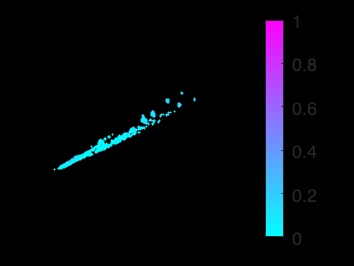

pcshow(ptCloud.Location, ptCloud.Intensity / max(ptCloud.Intensity))
title(filepath, 'Interpreter','none')
xlabel("X")
ylabel("Y")
zlabel("Z")
colorbar
colormap("cool")